# **EAS 4610 Final Project**

**Madalene Henggeler, Aravind Ganesan**

## **Introduction**

*(What is the main theme? Why is it important?**What observations, models, etc. are used by others that are different from what you are doing in the project?)*

The main theme in looking at this topic is predicting how tsunami wave propagation occurs through water. This topic is important because tsunami models can help to judge impact on coastlines and communities nearby. Tsunamis often occur with little time to predict and prepare, so being able to model how a wave might propagate can help for long-term preparations of communities.

The main paper that was reviewed for this project considers that change in sea level over time comes from advection due to velocity as well as the volume flux as ocean floor depth decreases. The model that is to be explored in this notebook is very similar, though a more exploratory approach will be applied to consider the stability of each numerical method and how they can be implemented.

## **Equations**

*(What are the fundamental physical/chemical/etc. processes?* *Relevant equations and potentially where they come from (i.e. how they are derived**). **Describe all terms and parameters**. * *Describe any assumptions being made)*

For now, we are assuming that this model is made in a narrow, frictionless channel so that we can consider it to be 1D. Friction effects are ignored for this simple model, and for now, depth is considered to be constant at each point. When a disturbance occurs from an earthquake, it is also assumed that there is instant displacement at the center, where the tsunami originates. This wave propagation can be described by a typical advection equation. 

In these equations, c is a variable known as phase velocity, g is gravitational acceleration, and H is the total depth of the ocean. ζ is the sea level amplitude, and T is the time step while h is the grid spacing. q is the Courant number, and for stability, this value must be less than 1. 

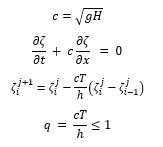

## **Numerical Methods**

*(Describe the numerical methods used: Why did you choose to use these methods?)*

We plan on using the Forward Euler Method & Crank-Nicholson Method. The forward Euler method was discussed within the research. However, the Crank-Nicholson method tends to be more accurate, so we plan to explore that method as well.

%Parameters
g = 9.81; %
H = $$; %

%Steps
dt =$$; %seconds 
dz = 2000; %m
C =sqrt(g*H);

t = tf / dt;
z = zf/dz;

%Setup Matrix problem
data_k = [((1-C)*ones(z,1)), (C*ones(z,1)), zeros(z,1)];
M_k = spdiags(data_k, -1:1, z, z);
zeta = nan(z,t);

%Boundary Condition 
zeta(1,1) = 1; %no-flux boundary condition
zeta(1,2) = 0; %no-flux boundary condition
zeta(2,1) = 0; %no-flux boundary condition

%initial condition - tbd
for k=3:z
    zeta(k,1) = $$;
end

%Solve matrix problem
for i=1:t-1
    zeta(:,i+1) = M_k * J(:,i);
end

## **Results**

*(**What simulations did you run with the model? Describe the results.* *How do the results compare with any known solutions or data?* *How do the results change with different methods, time steps, grid spacing, or model parameters?* *What did the model tell you about the process you were studying?* *How could the model be improved in terms of methods used or processes included**?)*

## **Figures**

*(**At least 4 figures describing results**. **Have all axes labeled**. **Variables have units**. **Everything is readable**. **Colors, lines, contours, etc. are all easy to discern**)*

## **Video Walkthrough**

*(**Either linked at top or embedded in notebook**. **Includes all team members**)*

## **References**

Kowalik, Z. (2012) Introduction to Numerical Modeling of Tsunami Waves. Institute of Marine Science University of Alaska, Fairbank. 